# Debugowanie

Poniżej, w osobnych sekcjach, przedstawiono zadania, które zostały już zrobione. Mają one błędy które należy poprawić zmieniając najlepiej jak najmniej w samym kodzie. Każdą poprawę błędu należy oznaczyć komentarzem i opisać w jaki sposób to poprawiono. Poniżej przykład takiego komentarza.

i = 0;
% disp('Zmienna i ma wartość ' + i)    % Stara wersja - char + double dawał liczby a nie litery
disp("Zmienna i ma wartość " + i)    % Nowa wersja - zmieniono char na string

Zmienna i ma wartość 0


## Parking

Parkowanie przez pierwszą godzinę jest darmowe. Druga godzina kosztuje 4 złote, a każda kolejna o **2 złote więcej**. W ciągu dnia jest maksymalnie 8 płatnych godzin. Stwórz program, który weźmie liczbę godzin ze slidera (wartości od 0 do 24), policzy cenę za parking i wyświetli ją na ekranie.  

*W poniższym programie nie działa obliczanie ceny przy wszystkich czasach ze slidera.*

clear;
czas = 1;
darmoweGodziny = 1;
cenaPoczatkowa = 4;
przyrostCeny   = 2;

% Oblicz cenę
if czas > 1
    liczbaPlatnychGodzin = czas - darmoweGodziny;
    cenaZaGodziny = (0 : liczbaPlatnychGodzin - 1) * przyrostCeny + cenaPoczatkowa;
    if czas > 8
        cena = sum(cenaZaGodziny(1 : 8));
    else
        cena = sum(cenaZaGodziny(1 : liczbaPlatnychGodzin));
    end
else
    cena = 0
end

cena = 0


% Pokaż wynik
fprintf("Cena za %ih parkingu: %.2f zł", czas, cena)

Cena za 1h parkingu: 0.00 zł

## Chińczyk

Aby przejść pionkiem w grze planszowej Chińczyk do bezpiecznej strefy należy przesunąć się o dokładnie 40 pozycji. Stwórz program, który, przy użyciu pętli while, będzie losować rzuty kostką (funkcja randi) i obliczy ile potrzeba tur, aby dostać się do bezpiecznej strefy. Jeżeli wyrzuci się 6, to dostaje się dodatkowy ruch w turze.

Następnie wsadź cały program w pętlę for, aby powtórzyć operację wiele razy i policz średnią potrzebnych ruchów do dostania się do bezpiecznej strefy (**powinno wyjść: 10.21**).

*Nie działa i zawiera błędy logiczne*

clear
NTries = 1e4;
NMoves = zeros(NTries, 1);
LiczbaPol = 40;
tic
for i = 1 : NTries
    NMoves(i) = simChinczyk(LiczbaPol);
end
toc

Elapsed time is 0.064462 seconds.


fprintf("Średnio potrzeba %.2f ruchów.", mean(NMoves))

Średnio potrzeba 10.22 ruchów.

# Klasy struct i cell

% Przykład struktury
clear;
A.imie        = "Marek";
A.nazwisko    = "Markowski";
A(2).imie     = "Adam";
A(2).nazwisko = "Adamowski"

A = 1×2 struct array with fields:
    imie
    nazwisko



% Przykład cell
B{1} = 0 : 50;
B{2} = 0 : 10

B = 1×2 cell array
    {[0 1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27 28 29 30 31 32 33 34 35 36 37 38 39 40 41 42 43 44 45 46 47 48 49 50]}    {[0 1 2 3 4 5 6 7 8 9 10]}


## Generacja sygnału sinusoidalnego

Utwórz strukturę **sInfo**, która będzie zawierać następujące informacje o sygnale sinusoidalnym $s=A\;\sin \left(2\pi f\cdot t+\textrm{phi}\right)$

- **A** = 2: amplituda

- **f** = 1: częstotliwość (ile razy na sekundę się powtarza)

- **phi** = 0: przesunięcie fazowe (w radianach)

- **fs** = 10: częstotliwość próbkowania (krok wektora czasu)

- **T** = 2: czas trwania

clear
sinfo.A = 2;
sinfo.f = 1

sinfo = struct with fields:
    A: 2
    f: 1


sinfo.phi = 0;
sinfo.fs = 10;
sinfo.T = 2;

Następnie wygeneruj ten wektor czasu **t1** i sygnał **s1** przy pomocy utworzonej struktury. Wygenerowany wektor czasu powinien mieć dokładnie **20 elementów**.

t1 = 0 : 1/sinfo.fs : sinfo.T-1/sinfo.fs;
s1 = sinfo.A*sin(2*pi*sinfo.f * t1 + sinfo.phi)

s1 =          0    1.1756    1.9021    1.9021    1.1756    0.0000   -1.1756   -1.9021   -1.9021   -1.1756   -0.0000    1.1756    1.9021    1.9021    1.1756    0.0000   -1.1756   -1.9021   -1.9021   -1.1756


Pokaż wygenerowany sygnał na wykresie. Powinien on wyglądać w ten sposób:

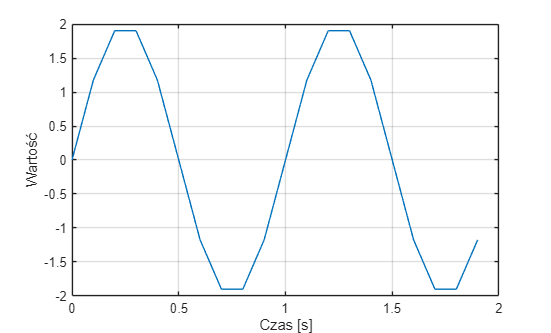

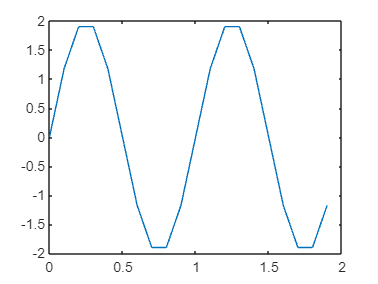

xlabel="Czas[s]";
ylabe="Wartość";
title="";
grid on;
plot(t1,s1);

Następnie dodaj drugi zestaw wartości do zmiennej **sInfo** (np.: sInfo(2).A = 2) o wartościach: 

- A = 1

- f = 2

- phi = π/4

- fs = 100

- T = 1

sinfo(2).A = 1;
sinfo(2).f = 2;
sinfo(2).phi = pi/4;
sinfo(2).fs = 100;
sinfo(2).T = 1;

W pętli for wygeneruj oba sygnały dla obu zestawów wartości. Wynik (zarówno **t** jak i **s**) każde z tych iteracji wpisz do zmiennej typu cell oraz wyświetl na wykresie. Cały ten punkt najłatwiej będzie zrobić wewnątrz jednej pętli for. Wynik powinien wyglądać w ten sposób:

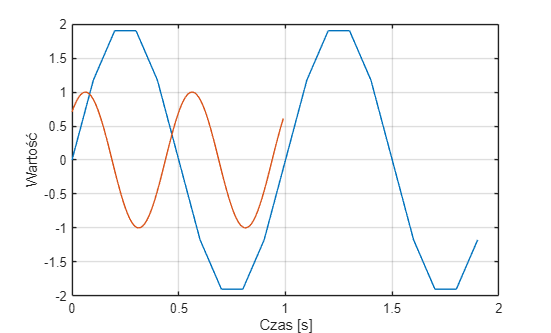

t2 = 0 : 1/sinfo(2).fs : sinfo(2).T-1/sinfo(2).fs;
s2 = sinfo(2).A*sin(2*pi*sinfo(2).f * t2 + sinfo(2).phi)

s2 =     0.7071    0.7902    0.8607    0.9178    0.9603    0.9877    0.9995    0.9956    0.9759    0.9409    0.8910    0.8271    0.7501    0.6613    0.5621    0.4540    0.3387    0.2181    0.0941   -0.0314   -0.1564   -0.2790   -0.3971   -0.5090   -0.6129   -0.7071   -0.7902   -0.8607   -0.9178   -0.9603   -0.9877   -0.9995   -0.9956   -0.9759   -0.9409   -0.8910   -0.8271   -0.7501   -0.6613   -0.5621   -0.4540   -0.3387   -0.2181   -0.0941    0.0314    0.1564    0.2790    0.3971    0.5090    0.6129


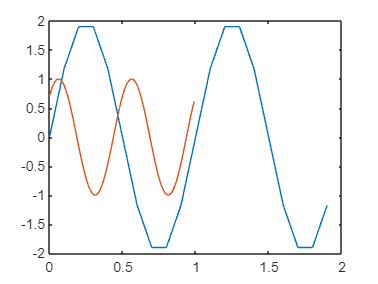

plot(t1, s1, t2, s2);


S{1} = s1

S = 1×1 cell array
    {[0 1.1756 1.9021 1.9021 1.1756 2.4493e-16 -1.1756 -1.9021 -1.9021 -1.1756 -2.2662e-15 1.1756 1.9021 1.9021 1.1756 7.3479e-16 -1.1756 -1.9021 -1.9021 -1.1756]}


S{2} = s2

S = 1×2 cell array
    {[0 1.1756 1.9021 1.9021 1.1756 2.4493e-16 -1.1756 -1.9021 -1.9021 -1.1756 -2.2662e-15 1.1756 1.9021 1.9021 1.1756 7.3479e-16 -1.1756 -1.9021 -1.9021 -1.1756]}    {[0.7071 0.7902 0.8607 0.9178 0.9603 0.9877 0.9995 0.9956 0.9759 0.9409 0.8910 0.8271 0.7501 0.6613 0.5621 0.4540 0.3387 0.2181 0.0941 -0.0314 -0.1564 -0.2790 -0.3971 -0.5090 -0.6129 -0.7071 -0.7902 -0.8607 -0.9178 -0.9603 -0.9877 -0.9995 -0.9956 -0.9759 -0.9409 -0.8910 -0.8271 -0.7501 -0.6613 -0.5621 -0.4540 -0.3387 -0.2181 -0.0941 0.0314 0.1564 0.2790 0.3971 0.5090 0.6129 0.7071 0.7902 0.8607 0.9178 0.9603 0.9877 0.9995 0.9956 0.9759 0.9409 0.8910 0.8271 0.7501 0.6613 0.5621 0.4540 0.3387 0.2181 0.0941 -0.0314 -0.1564 -0.2790 -0.3971 -0.5090 -0.6129 -0.7071 -0.7902 -0.8607 -0.9178 -0.9603 -0.9877 -0.9995 -0.9956 -0.9759 -0.9409 -0.8910 -0.8271 -0.7501 -0.6613 -0.5621 -0.4540 -0.3387 -0.2181 -0.0941 0.0314 0.1564 0.2790 0.3971 0.5090 0.6129]}


T{1} = t1

T = 1×1 cell array
    {[0 0.1000 0.2000 0.3000 0.4000 0.5000 0.6000 0.7000 0.8000 0.9000 1.0000 1.1000 1.2000 1.3000 1.4000 1.5000 1.6000 1.7000 1.8000 1.9000]}


T{2} = t2

T = 1×2 cell array
    {[0 0.1000 0.2000 0.3000 0.4000 0.5000 0.6000 0.7000 0.8000 0.9000 1.0000 1.1000 1.2000 1.3000 1.4000 1.5000 1.6000 1.7000 1.8000 1.9000]}    {[0 0.0100 0.0200 0.0300 0.0400 0.0500 0.0600 0.0700 0.0800 0.0900 0.1000 0.1100 0.1200 0.1300 0.1400 0.1500 0.1600 0.1700 0.1800 0.1900 0.2000 0.2100 0.2200 0.2300 0.2400 0.2500 0.2600 0.2700 0.2800 0.2900 0.3000 0.3100 0.3200 0.3300 0.3400 0.3500 0.3600 0.3700 0.3800 0.3900 0.4000 0.4100 0.4200 0.4300 0.4400 0.4500 0.4600 0.4700 0.4800 0.4900 0.5000 0.5100 0.5200 0.5300 0.5400 0.5500 0.5600 0.5700 0.5800 0.5900 0.6000 0.6100 0.6200 0.6300 0.6400 0.6500 0.6600 0.6700 0.6800 0.6900 0.7000 0.7100 0.7200 0.7300 0.7400 0.7500 0.7600 0.7700 0.7800 0.7900 0.8000 0.8100 0.8200 0.8300 0.8400 0.8500 0.8600 0.8700 0.8800 0.8900 0.9000 0.9100 0.9200 0.9300 0.9400 0.9500 0.9600 0.9700 0.9800 0.9900]}


for i = 1 : length(S)
    plot(T{i},S{i})
    hold on
end
hold off